Fourier Transform

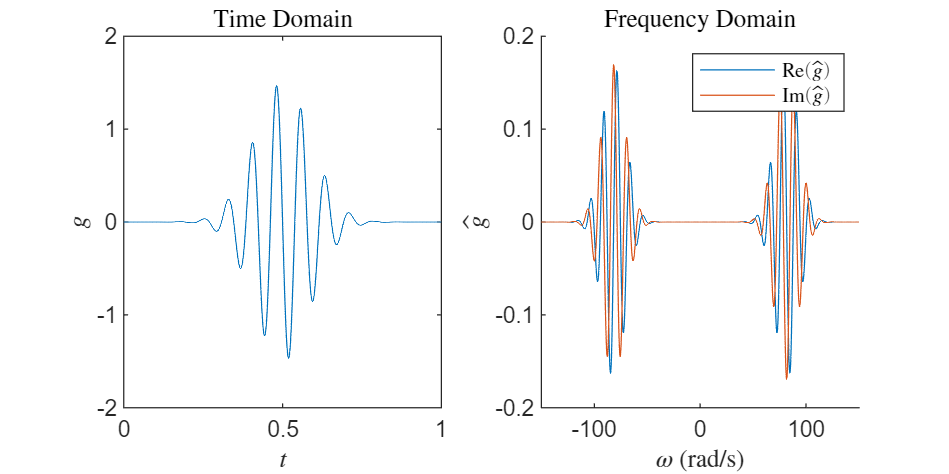

% This plots the Gaussian-modulated sinusoid and it's Fourier transform
A = 1.5; % Amplitude
f0 = 13; % Carrier frequency (Hz)
c = 0.09; % Gaussian "width"
t0 = 0.5; % Center position (s)
omega0 = f0*2*pi; % Angular frequency (rad/s)
 

ylims = [-2,2];
tlims = [0.0,1];
omegaLims = [-150,150];
ghatLims = [-0.2,0.2];

% Compute g
t = linspace(0,1,5e3);
g = A*sin(omega0*t).*exp(-(t-t0).^2/(2*c^2));

% Compute ghat 
omega = linspace(-250,250,5e3);
ghat = -A*sqrt(pi/2)*1i*c.*(exp(-0.5*(omega-omega0).*(c^2*omega-c^2*omega0+2*t0*1i)) - ...
                            exp(-0.5*(omega+omega0).*(c^2*omega+c^2*omega0+2*t0*1i)));

% Plots a Gaussian modulated sinusoid
% in time and frequency domains (real/imaginary part)
figure("Position",[1 1 800 400])

subplot(1,2,1)
t = linspace(0,1,5e3);
g = A*sin(omega0*t).*exp(-(t-t0).^2/(2*c^2));
plot(t,g)
ylim(ylims)
xlim(tlims)
xlabel("$t$","Interpreter","latex")
ylabel("$g$","Interpreter","latex")
title("Time Domain","Interpreter","latex")

subplot(1,2,2)
hold on
plot(omega,real(ghat))
plot(omega,imag(ghat))
ylim(ghatLims)
xlim(omegaLims)
xlabel("$\omega$ (rad/s)","Interpreter","latex")
ylabel("$\hat{g}$","Interpreter","latex")
legend("Re$(\hat{g})$","Im$(\hat{g})$","Interpreter","latex");
title("Frequency Domain","Interpreter","latex")

DFT

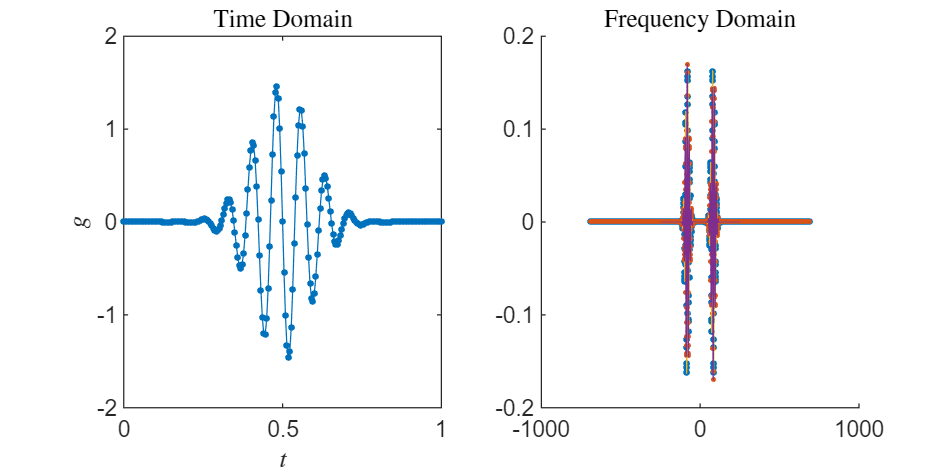

Fs = 220; % Sample rate (1/s)
tmax = 3;
tmin = 0;

% Compute g


t = (0:1/Fs:(N/Fs-1/Fs)) + tmin;
N = length(t);

g = A*sin(omega0*t).*exp(-(t-t0).^2/(2*c^2));

gdft = fft(g);
ghatd = 1/Fs*(fftshift(gdft));

omegad = 2*pi*([-N/2:N/2-1])*Fs/N;


% Plots a Gaussian modulated sinusoid
% in time and frequency domains (real/imaginary part)
figure("Position",[1 1 800 400])

colors = lines(2);
subplot(1,2,1)
plot(t,g,'-','markersize',6,'color',lines(1))
hold on
plot(t,g,'.','markersize',8,'color',lines(1))
ylim(ylims)
xlim([tmin,tmax])
xlim([0,1])
xlabel("$t$","Interpreter","latex")
ylabel("$g$","Interpreter","latex")
title("Time Domain","Interpreter","latex")

subplot(1,2,2)
hold on
plot(omegad,real(ghatd),'.',"color",colors(1,:),'MarkerSize',8)
plot(omegad,imag(ghatd),'.',"color",colors(2,:))
% plot(omegad,real(ghatd),'-',"color",colors(1,:))
% plot(omegad,imag(ghatd),'-',"color",colors(2,:))
plot(omega,real(ghat))
plot(omega,imag(ghat))
% ylim(ghatLims)
% xlim(omegaLims)
% xlabel("$\omega$ (rad/s)","Interpreter","latex")
% ylabel("$\hat{g}$","Interpreter","latex")
% legend("Re$(\hat{g})$","Im$(\hat{g})$","Interpreter","latex");
title("Frequency Domain","Interpreter","latex")